%% read parameters relating to system configuration in each one's own folder
paramsFilename ="params";
% preparet to pass paramsdata cell to each parfor
paramsdata = readcell(paramsFilename);
% extract params to base ws
assign_parameters(paramsdata);
%% calcuate and store data .mat
% autoSetWorkers()
for i = 1:numSteps
    % Calculate the actual temperature value
    stepValue = startTemp + (i-1) * stepTemp;
    calc_loopParameterVsE(paramsdata,stepValue);
end

%% plot by reading .mat
filePattern = eval(filePattern);

% for terminali = 1:numLeads
%     for terminalj = 1:numLeads
%         plot_and_save(filePattern, terminali, terminalj, plotCondition, dymLegend, strLegend,stepTemp,E_start,E_end);
%     end
% end

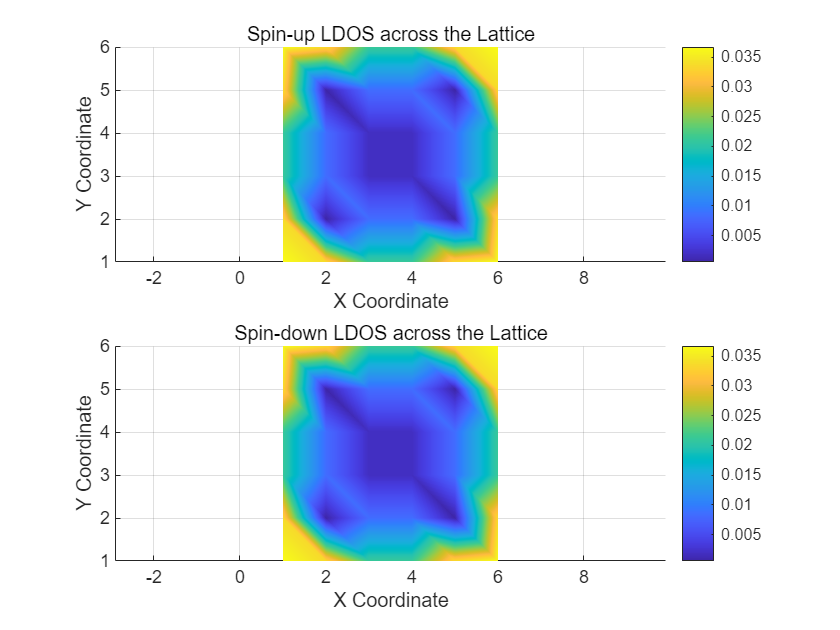

E_lower=-0.1;
E_upper=0.1;
isSpin=true;
plot_ldos_surface(results_struct.E, results_struct.rho_jj, E_lower, E_upper, Nx, Ny, isSpin)

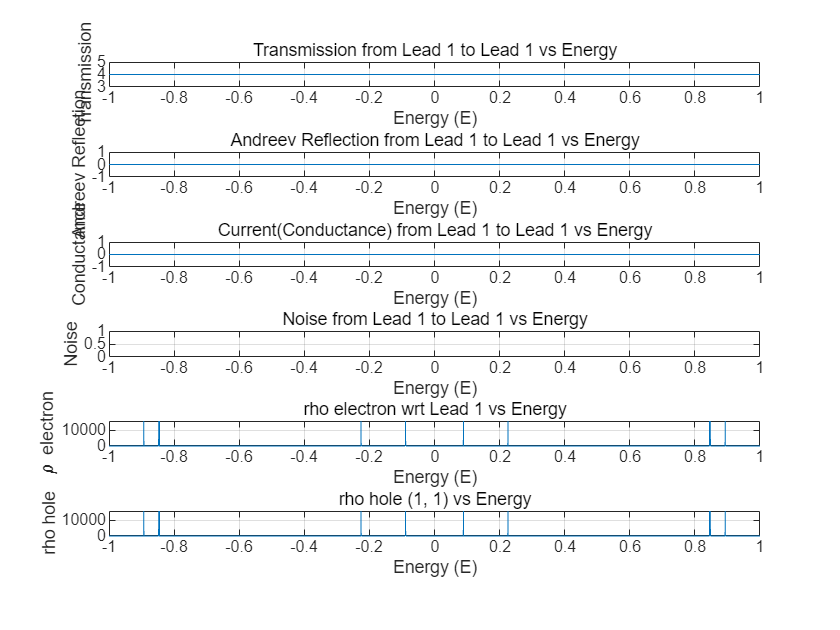

plot_all_vs_E(results_struct, 1, 1, [-1 1])

clear all
% Parameters
Ny = 6; % Number of lattice sites in y-direction for each chain
Nx = 6; % Number of chains (x-direction)
lambda = 1; % Hopping amplitude
lambda_s=1;
mu = -2; % Chemical potential
m = 5; % Mass
Delta=5; % spin singlet paring

% Pauli matrices and identity matrices
sigma_x = [0, 1; 1, 0];
sigma_y = [0, -1i; 1i, 0];
sigma_z = [1, 0; 0, -1];
I_spin = eye(2);
I_chain = eye(Ny);
I_Nx = eye(Nx);

% On-site potential matrix for a single site
H_onsite = (3/2 * m * sigma_z - mu * I_spin);

% Single chain Hamiltonian along y-axis with NNN interactions
T_nn_y = 1i * lambda/2 * sigma_y - m/2 * sigma_z; % Nearest-neighbor hopping along y
H_y = kron(diag(ones(Ny-1, 1),1), T_nn_y) + kron(diag(ones(Ny-1, 1), -1), T_nn_y') + ...
     kron(I_chain, H_onsite); % Add on-site term

% Adjust for NNN terms along y
T_nnn_y = m/8  * sigma_z; % NNN term
H_nnn_y = kron(diag(ones(Ny-2, 1), 2) , T_nnn_y)+ kron(diag(ones(Ny-2, 1), -2),T_nnn_y');
H_y = H_y + H_nnn_y; % Incorporate NNN along y

% X-axis hopping (nearest neighbor) and NNN interaction
T_nn_x = 1i * lambda/2 * sigma_x - m/2 * sigma_z; % Assuming uniform hopping along x
H_nn_x01 = kron(diag(ones(Ny, 1)) , T_nn_x);

% NNN interaction along x
T_nnn_x = m/8 * sigma_z; % Assuming similar form as NNN y for simplicity
H_nnn_x01 = kron(diag(ones(Ny, 1)) , T_nnn_x);

% Assemble full 2D Hamiltonian with NNN
H_full = kron(I_Nx, H_y) + ... % Diagonal blocks (chains along y)
          kron(diag(ones(Nx-1, 1), 1), H_nn_x01) + ... % Right off-diagonal blocks (hopping to right chain)
          kron(diag(ones(Nx-1, 1), -1), H_nn_x01' )+...; % Left off-diagonal blocks (Hermitian conjugate)
          kron(diag(ones(Nx-2, 1), 2), H_nnn_x01) + ... % Next Right off-diagonal blocks (hopping to next right chain)
          kron(diag(ones(Nx-2, 1), -2), H_nnn_x01' ); % Left off-diagonal blocks (Hermitian conjugate)
H_BdG=kron(H_full,[1,0;0,0])+kron(conj(H_full),[0,0;0,-1]);

H_Delta_spin_cell = [
    0,          0,          0,          Delta;
    0,          0,          -conj(Delta), 0;
    0,          -Delta,     0,          0;
    conj(Delta), 0,          0,          0
];
H_Delta =kron(eye(Nx*Ny),H_Delta_spin_cell);
H_total=H_BdG+H_Delta;
disp(eig(H_total))

  -23.6069
  -21.3322
  -21.3315
  -19.0589
  -18.6074
  -18.6074
  -16.3671
  -16.3668
  -16.3394
  -16.3360
  -15.0648
  -15.0648
  -14.5815
  -14.5815
  -14.1004
  -14.1004
  -13.6220
  -12.8411
  -12.7997
  -12.7988
  -12.3148
  -12.3148
  -11.3949
  -11.3861
  -10.5754
  -10.5733
  -10.0923
  -10.0923
   -9.6062
   -9.6055
   -9.1671
   -8.3172
   -7.8829
   -7.8672
   -7.8643
   -7.8643
   -7.3875
   -7.3873
   -6.5916
   -6.1209
   -6.0943
   -5.6473
   -5.6431
   -5.6329
   -5.6177
   -5.6132
   -5.2107
   -4.7852
   -4.7561
   -4.3505
   -4.3424
   -4.3421
   -3.8635
   -3.8631
   -3.5255
   -3.5255
   -3.4911
   -3.4861
   -3.1336
   -3.1003
   -3.0284
   -2.2832
   -2.2633
   -2.1717
   -1.9435
   -1.9392
   -1.2246
   -1.0033
   -0.9820
   -0.9812
   -0.2926
   -0.0679
    0.0679
    0.2926
    0.9812
    0.9820
    1.0033
    1.2246
    1.9392
    1.9435
    2.1717
    2.2633
    2.2832
    3.0284
    3.1003
    3.1336
    3.4861
    3.4911
    3.5255
    3.5255
    3.8631

% Define vortices with positions and fluxes
vortices.A = [Nx/2+0.5, Ny/2+0.5, 0.5];  % Vortex type A at (0, 0) with flux 0.5
vortices.B = [Nx/2+0.5, Ny/2+0.5, 0.5];  % Vortex type B at (0, 0) with flux 0.5
ifSpin=true;
H_total=gauging(H_total, Nx, Ny, lambda_s, vortices,ifSpin);
disp(eig(H_total))

  -23.5396
  -21.4379
  -21.2323
  -19.0688
  -18.6126
  -18.5897
  -16.4988
  -16.4287
  -16.2863
  -16.2638
  -15.0714
  -15.0628
  -14.5726
  -14.5535
  -14.1402
  -14.1066
  -13.6461
  -12.8587
  -12.8061
  -12.7790
  -12.3148
  -12.2558
  -11.5345
  -11.3910
  -10.6293
  -10.4422
  -10.1164
  -10.0961
   -9.6414
   -9.5781
   -9.2137
   -8.3220
   -7.9314
   -7.8956
   -7.8538
   -7.8154
   -7.3866
   -7.3736
   -6.5944
   -6.1496
   -6.0996
   -5.7151
   -5.6957
   -5.6464
   -5.5386
   -5.4726
   -5.2165
   -4.8085
   -4.6953
   -4.3420
   -4.3318
   -4.3223
   -3.8264
   -3.8168
   -3.5168
   -3.5020
   -3.4989
   -3.4793
   -3.1294
   -3.1073
   -3.0014
   -2.2830
   -2.2422
   -2.1850
   -1.9444
   -1.9264
   -1.1631
   -1.0095
   -0.9841
   -0.9461
   -0.2763
   -0.0363
    0.0363
    0.2763
    0.9461
    0.9841
    1.0095
    1.1631
    1.9264
    1.9444
    2.1850
    2.2422
    2.2830
    3.0014
    3.1073
    3.1294
    3.4793
    3.4989
    3.5020
    3.5168
    3.8168

ishermitian(H_total)

ans = logical
   1


tic
inv(1*eye(size(H_total))-H_total)

ans =   -0.8858 + 0.0000i  -0.3425 - 0.3425i   0.5019 + 0.5019i   1.2518 + 0.0000i  -0.0550 - 0.0493i   0.4867 - 0.7309i  -0.6479 + 1.0626i   0.1308 + 0.1215i   0.5174 - 0.1017i   0.6292 - 0.0810i  -0.8700 + 0.1150i  -0.8276 + 0.2600i   0.3520 - 0.1466i  -0.5392 + 1.0015i   0.7977 - 1.4356i  -0.6298 + 0.2212i   0.1660 + 0.4016i  -1.1418 + 0.5960i   1.6566 - 0.8335i  -0.2781 - 0.7334i  -0.0158 + 0.9019i  -0.5493 - 0.4401i   0.8003 + 0.6067i   0.0506 - 1.4455i  -0.0550 + 0.0493i  -0.7309 + 0.4867i   1.0626 - 0.6479i   0.1308 - 0.1215i   0.2575 - 0.0000i  -0.1674 - 0.1674i   0.2142 + 0.2142i  -0.2412 + 0.0000i  -0.1597 + 0.0912i   0.3901 - 0.2870i  -0.5832 + 0.3480i   0.2209 + 0.0105i  -0.3448 - 0.1843i  -0.0987 + 0.2920i   0.0979 - 0.4526i   0.3442 + 0.2819i  -0.0676 - 0.4056i  -0.0369 - 0.1688i   0.0269 + 0.2139i   0.0800 + 0.4224i  -0.1989 - 0.0666i   0.5833 - 0.7472i  -0.7828 + 1.0739i   0.3498 - 0.0183i   0.5174 + 0.1017i  -0.0810 + 0.6292i
  -0.3425 + 0.3425i  -0.3102 + 0.0000i   0.

toc

历时 0.136642 秒。


Transform to k space

1d case,  now suit the current case



% Define the left transform matrix U_left (4x4)
U_left = diag([exp(-1i * k * y), exp(1i * k * y), exp(-1i * k * y), exp(1i * k * y)]);

函数或变量 'k' 无法识别。


% Number of rows in H_total
num_rows = size(H_total, 1);

% Initialize U_right as zeros with the correct size
U_right = zeros(num_rows, 4);

% Fill U_right with the correct block diagonal structure
for n = 1:num_rows/4
    row_start = (n-1)*4 + 1;
    row_end = n*4;
    U_right(row_start:row_end, :) = diag([exp(1i * k * n), exp(-1i * k * n), exp(1i * k * n), exp(-1i * k * n)]);
end

% Extract the y-th block of H_total
H_y_block = H_total((y-1)*4+1:y*4, :);

% Perform the transformation: U_left * H_y_block * U_right
H_transformed = U_left * H_y_block * U_right;

% Display the result
disp(H_transformed);


2d fourier

function H_transformed_r2k = transformBlock(kx, ky, x, y, H_total, Ny)
    % Define the left transform matrix U_left (4x4)
    U_left = eye(4);

    % Number of rows in H_total
    num_rows = size(H_total, 1);

    % Initialize U_right with the correct size
    U_right = zeros(num_rows, 4);

    % Fill U_right with the correct block diagonal structure
    for n = 1:(num_rows / 4)
        % Calculate the x and y indices from n
        x_index = ceil(n / Ny);
        y_index = mod(n-1, Ny) + 1;


        % Calculate the block start and end rows
        row_start = (n - 1) * 4 + 1;
        row_end = n * 4;

                % Directly set the diagonal entries of U_right
        U_right(row_start:row_end, :) = diag([
            exp(1i * kx * (x_index - x) + 1i * ky * (y_index - y)), ...
            exp(1i * kx * (x_index - x) + 1i * ky * (y_index - y)), ...
            exp(1i * kx * (x_index - x) + 1i * ky * (y_index - y)), ...
            exp(1i * kx * (x_index - x) + 1i * ky * (y_index - y))
        ]);
    end

    % Extract the (x, y) block of H_total
    block_start = (y - 1 + (x - 1) * Ny) * 4 + 1;
    block_end = block_start + 3;
    H_block = H_total(block_start:block_end, :);

    %  translation symmetry is preserved and k is a good quantum number, so
    %  only a slice of H_total is enough to fourier transform
    % Perform the transformation: U_left * H_block * U_right
    H_transformed_r2k = U_left * H_block * U_right;
end


kx = 1; % Wave number in x direction
ky = 1; % Wave number in y direction
x = 5; % The x-th block you want to transform
y = 5; % The y-th block you want to transform

% Call the function to get H_transformed
H_transformed = transformBlock(kx, ky, x, y, H_total,  Ny);
% Display the result
disp(H_transformed);

ishermitian(H_transformed)

Use above foureri trasform to draw energy dispersion

% sample region in r space
x=ceil(Nx/2);
y=ceil(Ny/2);
% Construct momentum space Hamiltonian
kx_vals = linspace(-pi, pi, 100);
ky_vals = linspace(-pi, pi, 100);
[kx_grid, ky_grid] = meshgrid(kx_vals, ky_vals);
unitCell_size=2*size(T_nn_y,1);
% 2 factor above for bdg space
E_k = zeros(length(kx_vals), length(ky_vals), unitCell_size);

for kx_idx = 1:length(kx_vals)
    for ky_idx = 1:length(ky_vals)
        kx = kx_grid(kx_idx, ky_idx);
        ky = ky_grid(kx_idx, ky_idx);

        % Initialize the Hamiltonian in momentum space
        H_k = transformBlock(kx, ky, x, y, H_total, Ny);
        


        % Compute eigenvalues
        E_k(kx_idx, ky_idx, :) = sort(real(eig(H_k)));
    end
end

% Plot the dispersion relation
figure;
for band = 1:unitCell_size
    surf(kx_grid, ky_grid, E_k(:,:,band));
    hold on;
end
xlabel('k_x');
ylabel('k_y');
zlabel('Energy');
title('Dispersion Relation');
hold off;
% Define k-space trajectory: M -> Gamma -> X -> M
k_M = [pi, pi];
k_Gamma = [0, 0];
k_X = [pi, 0];

num_points = 100;
k_path = [linspace(k_M(1), k_Gamma(1), num_points)', linspace(k_M(2), k_Gamma(2), num_points)';
          linspace(k_Gamma(1), k_X(1), num_points)', linspace(k_Gamma(2), k_X(2), num_points)';
          linspace(k_X(1), k_M(1), num_points)', linspace(k_X(2), k_M(2), num_points)'];
figure;
plot(k_path(:, 1), k_path(:, 2), 'o-', 'LineWidth', 1.5);


E_k_path = zeros(num_points * 3, unitCell_size);

% Calculate eigenvalues along the k-path
for k_idx = 1:size(k_path, 1)
    kx = k_path(k_idx, 1);
    ky = k_path(k_idx, 2);
    % Initialize the Hamiltonian in momentum space
    H_k = transformBlock(kx, ky, x, y, H_total, Ny);

    % Compute eigenvalues and sort them
    E_k_path(k_idx, :) = sort(real(eig(H_k)));
end

% Plot the band diagram
figure;
hold on;
for band = 1:unitCell_size
    plot(E_k_path(:, band), 'LineWidth', 1.5);
end
hold off;
set(gca, 'XTick', [1, num_points, 2*num_points, 3*num_points]);
set(gca, 'XTickLabel', {'M', '\Gamma', 'X', 'M'});
xlabel('k-point trajectory');
ylabel('Energy');
title('Band Diagram');
grid on;



% Parameters
Ny = 3; % Number of lattice sites in y-direction for each chain
Nx = 3; % Number of chains (x-direction)
lambda = 1; % Hopping amplitude
mu = 1; % Chemical potential
m = 0.5; % Mass

% Pauli matrices and identity matrices
sigma_x = [0, 1; 1, 0];
sigma_y = [0, -1i; 1i, 0];
sigma_z = [1, 0; 0, -1];
I_spin = eye(2);
I_chain = eye(Ny);
I_Nx = eye(Nx);

% On-site potential matrix for a single site
H_onsite = (3/2 * m * sigma_z - mu * I_spin);

% Nearest-neighbor hopping term in y-direction
T_nn_y = 1i * lambda/2 * sigma_y - m/2 * sigma_z;

% Next-nearest-neighbor hopping term in y-direction
T_nnn_y = m/8 * sigma_z;

% Nearest-neighbor hopping term in x-direction
T_nn_x = 1i * lambda/2 * sigma_x - m/2 * sigma_z;

% Next-nearest-neighbor hopping term in x-direction
T_nnn_x = m/8 * sigma_z;

% Construct single chain Hamiltonian along y-axis with NN and NNN interactions
H_y = kron(diag(ones(Ny-1, 1), 1), T_nn_y) + ...
      kron(diag(ones(Ny-1, 1), -1), T_nn_y') + ...
      kron(diag(ones(Ny-2, 1), 2), T_nnn_y) + ...
      kron(diag(ones(Ny-2, 1), -2), T_nnn_y') + ...
      kron(I_chain, H_onsite);

% Hopping between chains along x-axis
H_hop_x = kron(diag(ones(Nx-1, 1), 1), kron(I_chain, T_nn_x)) + ...
          kron(diag(ones(Nx-1, 1), -1), kron(I_chain, T_nn_x')) + ...
          kron(diag(ones(Nx-2, 1), 2), kron(I_chain, T_nnn_x)) + ...
          kron(diag(ones(Nx-2, 1), -2), kron(I_chain, T_nnn_x'));

% Construct the full Hamiltonian
H_full = kron(I_Nx, H_y) + H_hop_x;

% Display size of the full 2D Hamiltonian
disp('Size of the full 2D Hamiltonian:');
disp(size(H_full));

% Display the full Hamiltonian matrix
disp('Full 2D Hamiltonian matrix:');
disp(H_full);


$\Psi_{\boldsymbol{r}}=(\psi_{\boldsymbol{r}},i\sigma_{y}\psi_{\boldsymbol{r}}^{\dagger})^{T}=(c_{\boldsymbol{r}\uparrow},c_{\boldsymbol{r}\downarrow},c_{\boldsymbol{r}\downarrow}^{\dagger},-c_{\boldsymbol{r}\uparrow}^{\dagger})^{T}$

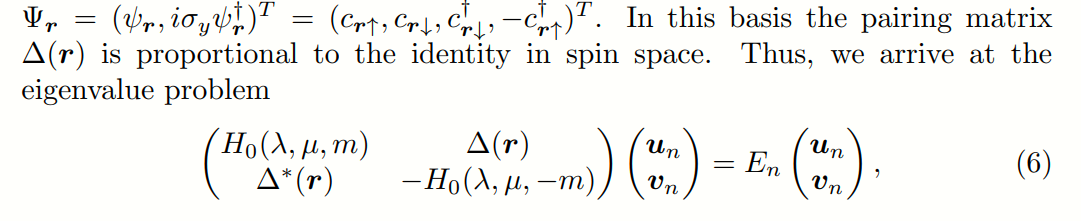

clear all
% Parameters
Ny = 3; % Number of lattice sites in y-direction for each chain
Nx = 3; % Number of chains (x-direction)
lambda = 1; % Hopping amplitude
mu = 0; % Chemical potential
m = 0.; % Mass

% Pauli matrices and identity matrices
sigma_x = [0, 1; 1, 0];
sigma_y = [0, -1i; 1i, 0];
sigma_z = [1, 0; 0, -1];
I_spin = eye(2);

% On-site potential matrix for a single site
H_onsite = (3/2 * m * sigma_z - mu * I_spin);

% Nearest-neighbor hopping term in y-direction
% Disperison differnt 
T_nn_y = 1i * lambda/2 * sigma_y- m/2 * sigma_z;

% Next-nearest-neighbor hopping term in y-direction
T_nnn_y = m/8 * sigma_z;

% Nearest-neighbor hopping term in x-direction
T_nn_x = 1i * lambda/2 * sigma_x- m/2 * sigma_z;

% Next-nearest-neighbor hopping term in x-direction
T_nnn_x = m/8 * sigma_z;

% Construct momentum space Hamiltonian
kx_vals = linspace(-pi, pi, 100);
ky_vals = linspace(-pi, pi, 100);
[kx_grid, ky_grid] = meshgrid(kx_vals, ky_vals);
unitCell_size=size(T_nnn_x,1);
E_k = zeros(length(kx_vals), length(ky_vals), unitCell_size);

for kx_idx = 1:length(kx_vals)
    for ky_idx = 1:length(ky_vals)
        kx = kx_grid(kx_idx, ky_idx);
        ky = ky_grid(kx_idx, ky_idx);

        % Initialize the Hamiltonian in momentum space
        H_k = H_onsite;
        
        % Nearest-neighbor hopping in y direction
        H_k = H_k + T_nn_y * exp(1i * ky) + T_nn_y' * exp(-1i * ky);
        
        % Next-nearest-neighbor hopping in y direction
        H_k = H_k + T_nnn_y * (exp(1i * 2 * ky) + exp(-1i * 2 * ky));
        
        % Nearest-neighbor hopping in x direction
        H_k = H_k + T_nn_x * exp(1i * kx) + T_nn_x' * exp(-1i * kx);
        
        % Next-nearest-neighbor hopping in x direction
        H_k = H_k + T_nnn_x * (exp(1i * 2 * kx) + exp(-1i * 2 * kx));

        % Compute eigenvalues
        E_k(kx_idx, ky_idx, :) = sort(real(eig(H_k)));
    end
end

% Plot the dispersion relation
figure;
for band = 1:unitCell_size
    surf(kx_grid, ky_grid, E_k(:,:,band));
    hold on;
end
xlabel('k_x');
ylabel('k_y');
zlabel('Energy');
title('Dispersion Relation');
hold off;
% Define k-space trajectory: M -> Gamma -> X -> M
k_M = [pi, pi];
k_Gamma = [0, 0];
k_X = [pi, 0];

num_points = 100;
k_path = [linspace(k_M(1), k_Gamma(1), num_points)', linspace(k_M(2), k_Gamma(2), num_points)';
          linspace(k_Gamma(1), k_X(1), num_points)', linspace(k_Gamma(2), k_X(2), num_points)';
          linspace(k_X(1), k_M(1), num_points)', linspace(k_X(2), k_M(2), num_points)'];
figure;
plot(k_path(:, 1), k_path(:, 2), 'o-', 'LineWidth', 1.5);


E_k_path = zeros(num_points * 3, unitCell_size);

% Calculate eigenvalues along the k-path
for k_idx = 1:size(k_path, 1)
    kx = k_path(k_idx, 1);
    ky = k_path(k_idx, 2);

    % Initialize the Hamiltonian in momentum space
    H_k = H_onsite;
    
    % Nearest-neighbor hopping in y direction
    H_k = H_k + T_nn_y * exp(1i * ky) + T_nn_y' * exp(-1i * ky);
    
    % Next-nearest-neighbor hopping in y direction
    H_k = H_k + T_nnn_y * (exp(1i * 2 * ky) + exp(-1i * 2 * ky));
    
    % Nearest-neighbor hopping in x direction
    H_k = H_k + T_nn_x * exp(1i * kx) + T_nn_x' * exp(-1i * kx);
    
    % Next-nearest-neighbor hopping in x direction
    H_k = H_k + T_nnn_x * (exp(1i * 2 * kx) + exp(-1i * 2 * kx));

    % Compute eigenvalues and sort them
    E_k_path(k_idx, :) = sort(real(eig(H_k)));
end

% Plot the band diagram
figure;
hold on;
for band = 1:unitCell_size
    plot(E_k_path(:, band), 'LineWidth', 1.5);
end
hold off;
set(gca, 'XTick', [1, num_points, 2*num_points, 3*num_points]);
set(gca, 'XTickLabel', {'M', '\Gamma', 'X', 'M'});
xlabel('k-point trajectory');
ylabel('Energy');
title('Band Diagram');
grid on;

figure;
plot(k_path(1:23, 1), k_path(1:23, 2), 'o-', 'LineWidth', 1.5);

ldf=setLeadMu([1,2 ,3,4], 0.01, 1d-6, 5, 5)

function plot_ldos_surface(E_values, rho_jj_values_cell, E_lower, E_upper, Nx, Ny, isSpin)
    % Filter E_values and rho_jj_values based on the specified energy range
    indices = find(E_values >= E_lower & E_values <= E_upper);
    E_filtered = E_values(indices);
    rho_jj_values_cell_filtered = rho_jj_values_cell(indices);
    
    % Convert cell array to matrix for easier manipulation
    rho_jj_values_matrix = cell2mat(rho_jj_values_cell_filtered);
    
    % Calculate LDOS by integrating rho_jj over the filtered energy values
    ldos = trapz(E_filtered, rho_jj_values_matrix, 2);
    if isSpin
        % Reshape and calculate LDOS for spin-up and spin-down separately
        ldos_reshaped = reshape(ldos, 2, []);
        ldos_spinup = ldos_reshaped(1,:);
        ldos_spindown = ldos_reshaped(2,:);
        % Reshape LDOS into matrices matching the lattice structure
        ldos_matrix_spinup = reshape(ldos_spinup, [Nx, Ny]);
        ldos_matrix_spindown = reshape(ldos_spindown, [Nx, Ny]);
    else
        % Reshape LDOS into a matrix matching the lattice structure
        ldos_matrix = reshape(ldos, [Nx, Ny]);
    end
    
    % Generate a meshgrid for plotting
    [X, Y] = meshgrid(1:Ny, 1:Nx); % Note: meshgrid uses (x, y) ordering
    
    if isSpin
        figure;
        % Spin-up LDOS
        subplot(2,1,1);
        surf(X, Y, ldos_matrix_spinup);
        shading interp; % Interpolate colors across faces for smooth appearance
        title('Spin-up LDOS across the Lattice');
        xlabel('X Coordinate');
        ylabel('Y Coordinate');
        zlabel('LDOS');
        colorbar;
        view(2); % 2D projection
        axis equal
        
        % Spin-down LDOS
        subplot(2,1,2);
        surf(X, Y, ldos_matrix_spindown);
        shading interp; % Interpolate colors across faces for smooth appearance
        title('Spin-down LDOS across the Lattice');
        xlabel('X Coordinate');
        ylabel('Y Coordinate');
        zlabel('LDOS');
        colorbar;
        view(2); % 2D projection
        axis equal
    else
        % Total LDOS
        figure;
        surf(X, Y, ldos_matrix);
        shading interp; % Interpolate colors across faces for smooth appearance
        title(sprintf('Local Density of States (LDOS) across energy interval [%d %d]',E_lower,E_upper));
        xlabel('X Coordinate');
        ylabel('Y Coordinate');
        zlabel('LDOS');
        colorbar; % Show a colorbar indicating the scale of LDOS
        view(2); % Change the view to a 2D projection
        axis equal
    end
end

function plot_all_vs_E(results_struct, i, j, xrange)
    % Extract data for each plot
    transmission_ij = cellfun(@(x) x(i, j), results_struct.transmission);
    andreev_ij = cellfun(@(x) x(i, j), results_struct.andreev);
    current_ij = cellfun(@(x) x(i, j), results_struct.current);
    noise_ij = cellfun(@(x) x(i, j), results_struct.noise);

    % Extracting the first derivative and Hessian for lead i and the (i,j) element of the Hessian
    rho_electron = results_struct.rho_electron_values;
    rho_hole = results_struct.rho_hole;

    % Create a figure for subplots
    figure;

    % Subplots for Transmission, Andreev Reflection, Conductance, and Noise
    subplot(6, 1, 1);
    plot(results_struct.E, transmission_ij);
    title(sprintf('Transmission from Lead %d to Lead %d vs Energy', i, j));
    xlabel('Energy (E)');
    ylabel('Transmission');
    xlim(xrange);
    ylim auto;
    grid on;

    subplot(6, 1, 2);
    plot(results_struct.E, andreev_ij);
    title(sprintf('Andreev Reflection from Lead %d to Lead %d vs Energy', i, j));
    xlabel('Energy (E)');
    ylabel('Andreev Reflection');
    xlim(xrange);
    ylim auto;
    grid on;

    subplot(6, 1, 3);
    plot(results_struct.E, current_ij );
    title(sprintf('Current(Conductance) from Lead %d to Lead %d vs Energy', i, j));
    xlabel('Energy (E)');
    ylabel('Conductance');
    xlim(xrange);
    ylim auto;
    grid on;

    subplot(6, 1, 4);
    plot(results_struct.E, noise_ij);
    title(sprintf('Noise from Lead %d to Lead %d vs Energy', i, j));
    xlabel('Energy (E)');
    ylabel('Noise');
    xlim(xrange);
    ylim auto;
    grid on;

    % Subplot for First Derivative
    subplot(6, 1, 5);
    plot(results_struct.E, rho_electron);
    title(sprintf('rho electron wrt Lead %d vs Energy', i));
    xlabel('Energy (E)');
    ylabel('\rho electron');
    xlim(xrange);
    ylim auto;
    grid on;

    % Subplot for Hessian element (i, j)
    subplot(6, 1, 6);
    plot(results_struct.E, rho_hole);
    title(sprintf('rho hole (%d, %d) vs Energy', i, j));
    xlabel('Energy (E)');
    ylabel('rho hole');
    xlim(xrange);
    ylim auto;
    grid on;
end